# OGLO notebook 4c

hnxj@github

### V4

>Finish TFR (6 areas)

>Temporal offset

>Alpha/Beta separate plots

>Gamma separate plots

>Spiking PFC/FEF to LFP other areas

>12 conditions*

>Friston 2009 FEM; First/Second level fig.5

xG = z{5};

y = squeeze(mean(mean(xG{1}{1}, 1), 2));
[p1, f1, t1] = pspectrum(y, 1000, "spectrogram", "FrequencyLimits", [0 100], "TimeResolution", 0.4, "OverlapPercent", 90);
pgx_v4 = zeros([12, size(p1)]);

parfor ik = 1:size(xG, 2)

    xG1 = xG{ik};

    for jk = 1:size(xG1, 2)

        xG2 = xG1{jk};

        for kk = 1:size(xG2, 1)

            for lk = 1:size(xG2, 2)

                y = squeeze(xG2(kk, lk, :));
                y = y - mean(y) / std(y);
                y(isinf(y)) = 0;
                y(isnan(y)) = 0;
                [p1temp, f, t] = pspectrum(y, 1000, "spectrogram", "FrequencyLimits", [0 100], "TimeResolution", 0.4, "OverlapPercent", 90);
                pgx_v4(ik, :, :) = squeeze(pgx_v4(ik, :, :)) + p1temp;
            
            end

        end

    end

    disp("cond : " + num2str(ik));

end

Starting parallel pool (parpool) using the 'Processes' profile ...
Connected to parallel pool with 12 workers.
cond : 4
cond : 7
cond : 3
cond : 2
cond : 11
cond : 6
cond : 12
cond : 10
cond : 8
cond : 9
cond : 5
cond : 1


y = squeeze(mean(xG3(:, 21, :), 1));
pspectrum(y, 1000, "spectrogram", "FrequencyLimits", [0 100], "TimeResolution", 0.4, "OverlapPercent", 90);

save("lfpData\TFRs05_OGLO_V4", "pgx_v4", "-v7.3");

for ik = 1:size(pgx, 2)

    for ij = 1:size(pgx, 1)
    
        pgx(ij, ik, :) = (pgx_v4(ij, ik, :))/mean(pgx_v4(ij, ik, 1:15));

    end

end

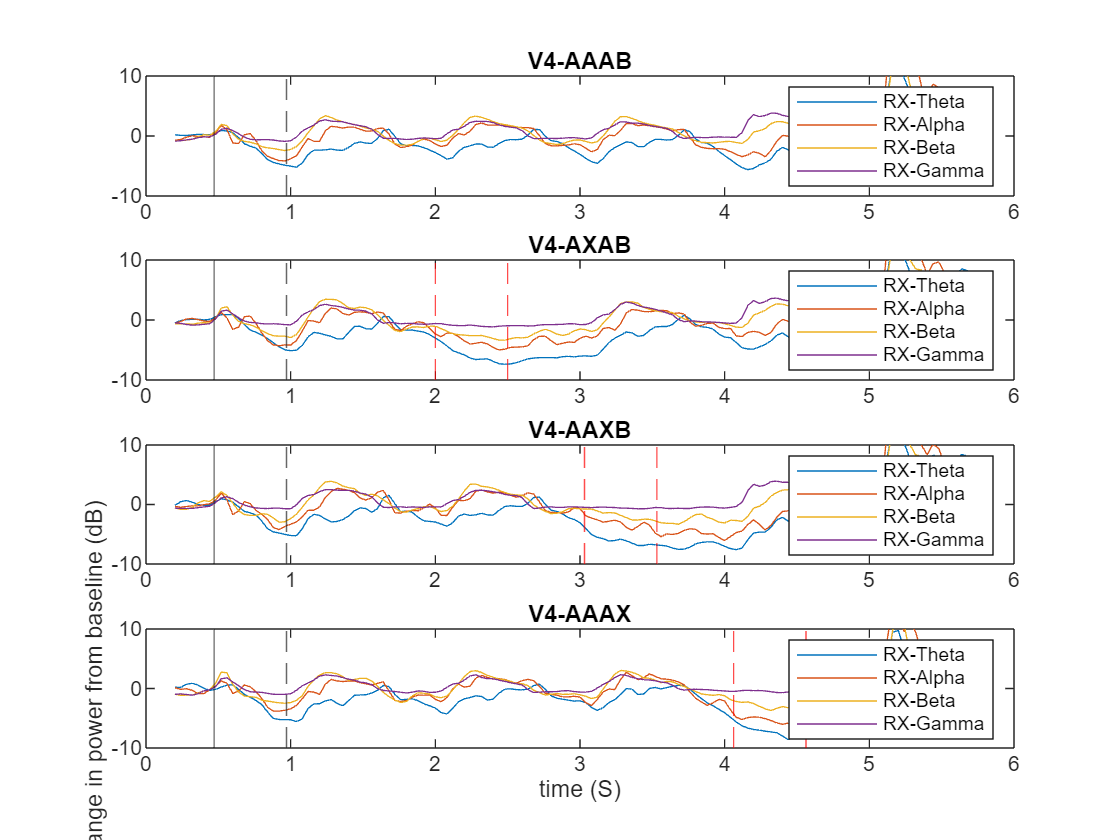

figure;
subplot(4, 1, 1);
y1t = smooth(squeeze(mean(pgx(1, 10:60, :))), 1);
y1a = smooth(squeeze(mean(pgx(1, 80:120, :))), 1);
y1b = smooth(squeeze(mean(pgx(1, 125:320, :))), 1);
y1g = smooth(squeeze(mean(pgx(1, 360:end, :))), 1);

plot(t, 10*log10((y1t)), "DisplayName", "RX-Theta");hold("on");
plot(t, 10*log10((y1a)), "DisplayName", "RX-Alpha");
plot(t, 10*log10((y1b)), "DisplayName", "RX-Beta");
plot(t, 10*log10((y1g)), "DisplayName", "RX-Gamma");
xline(0.471, "LineStyle", "-", "HandleVisibility", "off");
xline(0.971, "LineStyle", "--", "HandleVisibility", "off");
% xline(4.500, "LineStyle", "--", "HandleVisibility", "off");
legend();title("V4-AAAB");
ylim([-10 10]);
% xlim([0.4 5.0]);

subplot(4, 1, 2);
y1t = smooth(squeeze(mean(pgx(2, 10:60, :))), 2);
y1a = smooth(squeeze(mean(pgx(2, 80:120, :))), 2);
y1b = smooth(squeeze(mean(pgx(2, 125:320, :))), 2);
y1g = smooth(squeeze(mean(pgx(2, 360:end, :))), 2);

plot(t, 10*log10((y1t)), "DisplayName", "RX-Theta");hold("on");
plot(t, 10*log10((y1a)), "DisplayName", "RX-Alpha");
plot(t, 10*log10((y1b)), "DisplayName", "RX-Beta");
plot(t, 10*log10((y1g)), "DisplayName", "RX-Gamma");
xline(0.471, "LineStyle", "-", "HandleVisibility", "off");
xline(0.971, "LineStyle", "--", "HandleVisibility", "off");
xline(2.000, "LineStyle", "--", "HandleVisibility", "off", "Color", [1 0 0]);
xline(2.500, "LineStyle", "--", "HandleVisibility", "off", "Color", [1 0 0]);
legend();title("V4-AXAB");ylim([-10 10]);
% xlim([0.4 6.0]);

subplot(4, 1, 3);
y1t = smooth(squeeze(mean(pgx(3, 10:60, :))), 2);
y1a = smooth(squeeze(mean(pgx(3, 80:120, :))), 2);
y1b = smooth(squeeze(mean(pgx(3, 125:320, :))), 2);
y1g = smooth(squeeze(mean(pgx(3, 360:end, :))), 2);

plot(t, 10*log10((y1t)), "DisplayName", "RX-Theta");hold("on");
plot(t, 10*log10((y1a)), "DisplayName", "RX-Alpha");
plot(t, 10*log10((y1b)), "DisplayName", "RX-Beta");
plot(t, 10*log10((y1g)), "DisplayName", "RX-Gamma");
xline(0.471, "LineStyle", "-", "HandleVisibility", "off");
xline(0.971, "LineStyle", "--", "HandleVisibility", "off");
xline(3.031, "LineStyle", "--", "HandleVisibility", "off", "Color", [1 0 0]);
xline(3.531, "LineStyle", "--", "HandleVisibility", "off", "Color", [1 0 0]);
legend();title("V4-AAXB");ylim([-10 10]);
% xlim([0.4 6.0]);

subplot(4, 1, 4);
y1t = smooth(squeeze(mean(pgx(4, 10:60, :))), 2);
y1a = smooth(squeeze(mean(pgx(4, 80:120, :))), 2);
y1b = smooth(squeeze(mean(pgx(4, 125:320, :))), 2);
y1g = smooth(squeeze(mean(pgx(4, 360:end, :))), 2);

plot(t, 10*log10((y1t)), "DisplayName", "RX-Theta");hold("on");
plot(t, 10*log10((y1a)), "DisplayName", "RX-Alpha");
plot(t, 10*log10((y1b)), "DisplayName", "RX-Beta");
plot(t, 10*log10((y1g)), "DisplayName", "RX-Gamma");
xline(0.471, "LineStyle", "-", "HandleVisibility", "off");
xline(0.971, "LineStyle", "--", "HandleVisibility", "off");
xline(4.062, "LineStyle", "--", "HandleVisibility", "off", "Color", [1 0 0]);
xline(4.562, "LineStyle", "--", "HandleVisibility", "off", "Color", [1 0 0]);
ylabel("Change in power from baseline (dB)");
xlabel("time (S)");
legend();title("V4-AAAX");ylim([-10 10]);
% xlim([0.4 6.0]);

fname = "V4_TFRBandplot";
print(gcf,'-vector','-dsvg',fname +".svg");

### TEO

xG = z{6};

y = squeeze(mean(mean(xG{1}{1}, 1), 2));
[p1, f1, t1] = pspectrum(y, 1000, "spectrogram", "FrequencyLimits", [0 100], "TimeResolution", 0.4, "OverlapPercent", 90);
pgx_teo = zeros([12, size(p1)]);

parfor ik = 1:size(xG, 2)

    xG1 = xG{ik};

    for jk = 1:size(xG1, 2)

        xG2 = xG1{jk};

        for kk = 1:size(xG2, 1)

            for lk = 1:size(xG2, 2)

                y = squeeze(xG2(kk, lk, :));
                y = y - mean(y) / std(y);
                y(isinf(y)) = 0;
                y(isnan(y)) = 0;
                [p1temp, f, t] = pspectrum(y, 1000, "spectrogram", "FrequencyLimits", [0 100], "TimeResolution", 0.4, "OverlapPercent", 90);
                pgx_teo(ik, :, :) = squeeze(pgx_teo(ik, :, :)) + p1temp;
            
            end

        end

    end

    disp("cond : " + num2str(ik));

end

Starting parallel pool (parpool) using the 'Processes' profile ...


y = squeeze(mean(xG3(:, 21, :), 1));
pspectrum(y, 1000, "spectrogram", "FrequencyLimits", [0 100], "TimeResolution", 0.25, "OverlapPercent", 90);

save("lfpData\TFRs06_OGLO_TEO", "pgx_teo", "-v7.3");

for ik = 1:size(pgx, 2)

    for ij = 1:size(pgx, 1)
    
        pgx(ij, ik, :) = (pgx_teo(ij, ik, :))/mean(pgx_teo(ij, ik, 1:15));

    end

end

figure;
subplot(4, 1, 1);
y1t = smooth(squeeze(mean(pgx(1, 10:60, :))), 1);
y1a = smooth(squeeze(mean(pgx(1, 80:120, :))), 1);
y1b = smooth(squeeze(mean(pgx(1, 125:320, :))), 1);
y1g = smooth(squeeze(mean(pgx(1, 360:end, :))), 1);

plot(t, 10*log10((y1t)), "DisplayName", "RX-Theta");hold("on");
plot(t, 10*log10((y1a)), "DisplayName", "RX-Alpha");
plot(t, 10*log10((y1b)), "DisplayName", "RX-Beta");
plot(t, 10*log10((y1g)), "DisplayName", "RX-Gamma");
xline(0.471, "LineStyle", "-", "HandleVisibility", "off");
xline(0.971, "LineStyle", "--", "HandleVisibility", "off");
% xline(4.500, "LineStyle", "--", "HandleVisibility", "off");
legend();title("TEO-AAAB");
ylim([-15 20]);
% xlim([0.4 5.0]);

subplot(4, 1, 2);
y1t = smooth(squeeze(mean(pgx(2, 10:60, :))), 2);
y1a = smooth(squeeze(mean(pgx(2, 80:120, :))), 2);
y1b = smooth(squeeze(mean(pgx(2, 125:320, :))), 2);
y1g = smooth(squeeze(mean(pgx(2, 360:end, :))), 2);

plot(t, 10*log10((y1t)), "DisplayName", "RX-Theta");hold("on");
plot(t, 10*log10((y1a)), "DisplayName", "RX-Alpha");
plot(t, 10*log10((y1b)), "DisplayName", "RX-Beta");
plot(t, 10*log10((y1g)), "DisplayName", "RX-Gamma");
xline(0.471, "LineStyle", "-", "HandleVisibility", "off");
xline(0.971, "LineStyle", "--", "HandleVisibility", "off");
xline(2.000, "LineStyle", "--", "HandleVisibility", "off", "Color", [1 0 0]);
xline(2.500, "LineStyle", "--", "HandleVisibility", "off", "Color", [1 0 0]);
legend();title("TEO-AXAB");ylim([-15 20]);
% xlim([0.4 6.0]);

subplot(4, 1, 3);
y1t = smooth(squeeze(mean(pgx(3, 10:60, :))), 2);
y1a = smooth(squeeze(mean(pgx(3, 80:120, :))), 2);
y1b = smooth(squeeze(mean(pgx(3, 125:320, :))), 2);
y1g = smooth(squeeze(mean(pgx(3, 360:end, :))), 2);

plot(t, 10*log10((y1t)), "DisplayName", "RX-Theta");hold("on");
plot(t, 10*log10((y1a)), "DisplayName", "RX-Alpha");
plot(t, 10*log10((y1b)), "DisplayName", "RX-Beta");
plot(t, 10*log10((y1g)), "DisplayName", "RX-Gamma");
xline(0.471, "LineStyle", "-", "HandleVisibility", "off");
xline(0.971, "LineStyle", "--", "HandleVisibility", "off");
xline(3.031, "LineStyle", "--", "HandleVisibility", "off", "Color", [1 0 0]);
xline(3.531, "LineStyle", "--", "HandleVisibility", "off", "Color", [1 0 0]);
legend();title("TEO-AAXB");ylim([-15 20]);
% xlim([0.4 6.0]);

subplot(4, 1, 4);
y1t = smooth(squeeze(mean(pgx(4, 10:60, :))), 2);
y1a = smooth(squeeze(mean(pgx(4, 80:120, :))), 2);
y1b = smooth(squeeze(mean(pgx(4, 125:320, :))), 2);
y1g = smooth(squeeze(mean(pgx(4, 360:end, :))), 2);

plot(t, 10*log10((y1t)), "DisplayName", "RX-Theta");hold("on");
plot(t, 10*log10((y1a)), "DisplayName", "RX-Alpha");
plot(t, 10*log10((y1b)), "DisplayName", "RX-Beta");
plot(t, 10*log10((y1g)), "DisplayName", "RX-Gamma");
xline(0.471, "LineStyle", "-", "HandleVisibility", "off");
xline(0.971, "LineStyle", "--", "HandleVisibility", "off");
xline(4.062, "LineStyle", "--", "HandleVisibility", "off", "Color", [1 0 0]);
xline(4.562, "LineStyle", "--", "HandleVisibility", "off", "Color", [1 0 0]);
ylabel("Change in power from baseline (dB)");
xlabel("time (S)");
legend();title("TEO-AAAX");ylim([-15 20]);
% xlim([0.4 6.0]);

fname = "TEO_TFRBandplot";
print(gcf,'-vector','-dsvg',fname +".svg");